# ______________Computational Electromagnetics 

## _______________________________ Hw6-Q5

______________________Mohammadreza Arani         :::::::::::::         810100511

 __________________________________________1401/09/30   

clear; close all; clc;

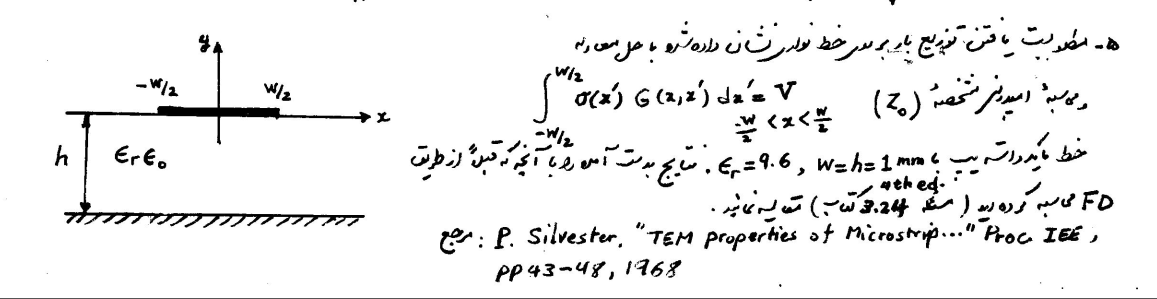

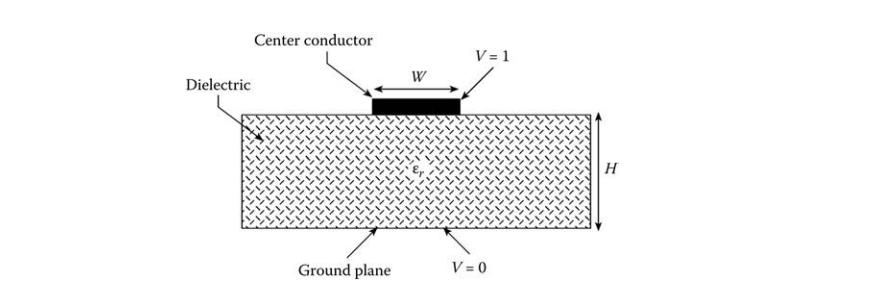

NN = [3  7 20 30 60 100 150 200 500 1000];
ER =9.6;

i =0 ;
Z = zeros(1,length(NN));

W  =1;
H  =1;


for N = NN
i = i +1;    
[ ~ , ~ ,~ , Z(i) ] = Impedance_MoM_Calc(N,ER,W,H);

disp(N+ "   |  " + Z(i)  );
disp("----------------");
end

3   |  50.0235


----------------


7   |  58.5266


----------------


20   |  65.6422


----------------


30   |  65.9336


----------------


60   |  66.2762


----------------


100   |  66.4386


----------------


150   |  66.5295


----------------


200   |  66.5787


----------------


500   |  66.6775


----------------


1000   |  66.7158


----------------


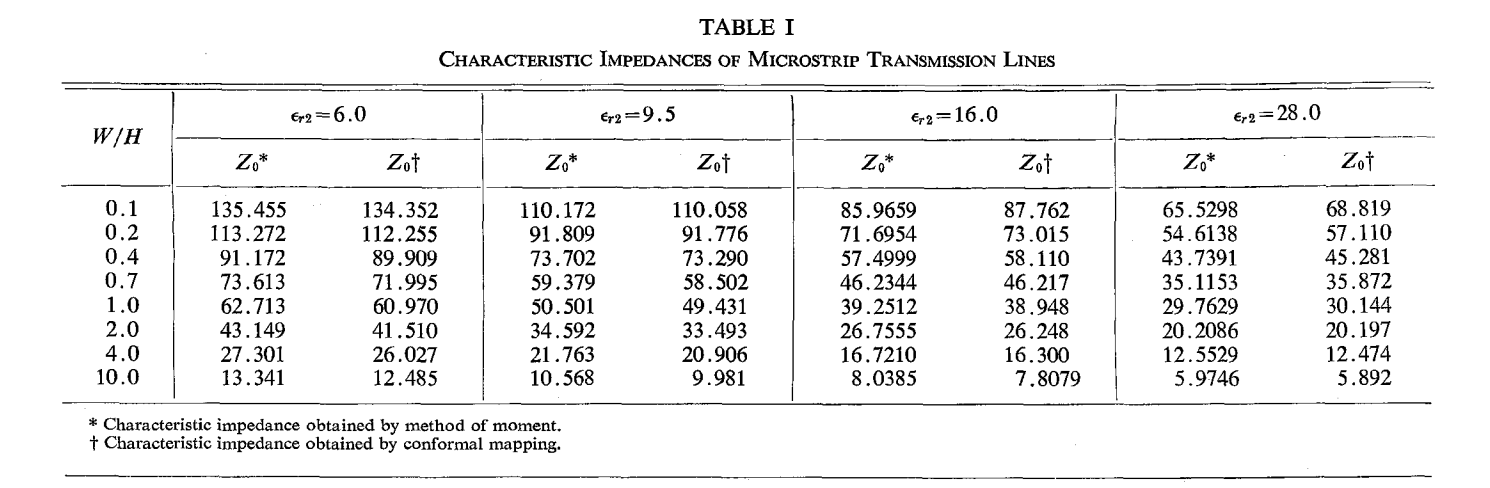

What we achieved here, is about 66.57 [ohm] !  --> Comparing to FD method, it took less time and the accuracy is considerable!

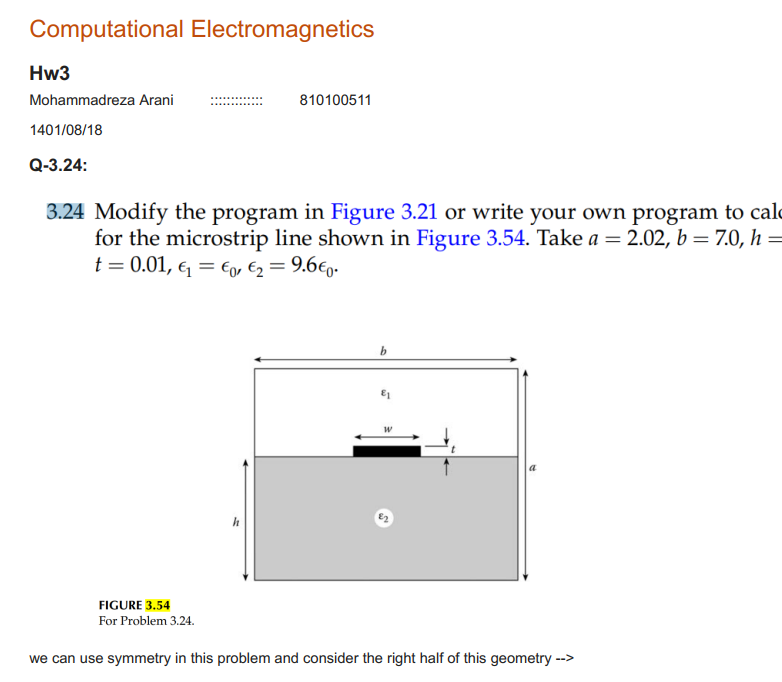

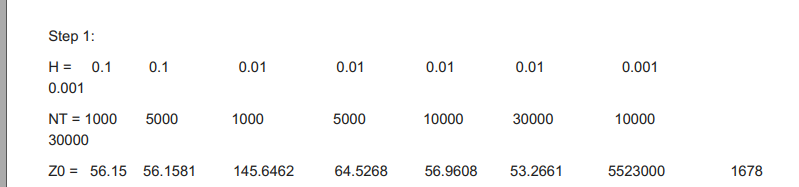

values obtained in FD method, shows tendacy to 65 [ohm] in high number of iterations!

** Both Values are almost the same and are reasonable **

function  [G ]  =  impedance_MoM_TEM_strips(N,ER,AIR , W,H)


%     vo = 3.0e08; % SPEED of LIGHT in free space  % Given

%     ER = 9.6; % Given

     Eo = 8.8541878176e-12; % F/m % Given
% 
%     H = 1.0; % Given
%     W = 1;

    G = zeros(N,N);
    C = G;

    if(AIR == 0)
     k = (ER-1)/(ER+1);
    else
        k=1;
    end

    Delta = W/N;

    for i=1:N
        for j=1:N
            SUM = 0;
            C(i,j) = Delta/H * abs(2*(i-1) - 2*(j-1) -1 ) ;
            for n = 1: 100
                SUM = SUM + k^(2*(n-1))*log( (   C(i,j)^2 + (4*n-2)^2  ) / ( C(i,j)^2 + (4*n-4)^2     )  )  + ...
                            k^(2*n-1)*log(   (   C(i,j)^2 + (4*n-2)^2  ) / ( C(i,j)^2 + (4*n)^2     )  ) ;
            end

            G(i,j) = 1/(4*pi*Eo) * SUM   ;

        end
    end
end

function [G , Capo , Cap , Zo] = Impedance_MoM_Calc(N,ER,W,H)

     AIR = 0;
     vo = 3.0e08; % SPEED of LIGHT in free space  % Given


     G = impedance_MoM_TEM_strips(N,ER,AIR , W,H);
     Alpha = inv(G)*ones(N,1);

     Cap = sum(Alpha,'all') ;  % F/m

     AIR =1;
     G_Air_Filled = impedance_MoM_TEM_strips(N,ER,AIR , W,H);
     Alpha_AIR_FIlled = inv(G_Air_Filled)*ones(N,1);
     Capo = sum(Alpha_AIR_FIlled,'all') ;  % F/m

     Zo =  1/ (vo * sqrt(Capo*Cap)   ) ;




end






